# **Question 1**

clear; clc;

load t
load u
load y

syms m1 m2 b1 b2 k1 k2 s

% Check out the REPORT file for the dynamics derives of the system.

A = [0, 1, 0, 0;
     0, 0, 1, 0;
     0, 0, 0, 1;
     -(k1*k2)/(m1*m2), -(b2*k1 + b1*k2)/(m1*m2), -(m2*(k1 + k2) + m1*k2 + b1*b2)/(m1*m2), -(m2*(b1 + b2) + m1*b2)/(m1*m2)];
B = [0; 0; 0; 1];
C = [k2/(m1*m2), b2/(m1*m2), 0, 0];

%%
% Forward Euler Discretization
T=0.1

T = 0.1000

Ad = T*A + eye(length(A))

$$Ad = \left(\begin{array}{cccc} 1 & \frac{1}{10} & 0 & 0\\ 0 & 1 & \frac{1}{10} & 0\\ 0 & 0 & 1 & \frac{1}{10}\\ -\frac{k_{1}\,k_{2}}{10\,m_{1}\,m_{2}} & -\frac{b_{1}\,k_{2}+b_{2}\,k_{1}}{10\,m_{1}\,m_{2}} & -\frac{m_{2}\,\left(k_{1}+k_{2}\right)+b_{1}\,b_{2}+k_{2}\,m_{1}}{10\,m_{1}\,m_{2}} & 1-\frac{b_{2}\,m_{1}+m_{2}\,\left(b_{1}+b_{2}\right)}{10\,m_{1}\,m_{2}} \end{array}\right)$$

Bd = T*B

Bd =          0
         0
         0
    0.1000


Cd = C

$$Cd = \left(\begin{array}{cccc} \frac{k_{2}}{m_{1}\,m_{2}} & \frac{b_{2}}{m_{1}\,m_{2}} & 0 & 0 \end{array}\right)$$

syms z;

% forming the transfer function
G = Cd*inv(z*eye(length(Ad)) - Ad)*Bd;

fprintf("\n\n G = \n")



 G = 



pretty(G)

k2   10 b2 (z - 1)
-- + -------------
#1         #1

where

   #1 == 100 b1 b2 - 10 b1 k2 - 10 b2 k1 - 1000 b1 m2 - 1000 b2 m1 - 1000 b2 m2 + k1 k2 + 100 k1 m2 + 100 k2 m1 + 100 k2 m2 + 10000 m1 m2

                    2               2               3               3               2               3              2              2
      - 3000 b1 m2 z  - 3000 b2 m1 z  + 1000 b1 m2 z  + 1000 b2 m1 z  - 3000 b2 m2 z  + 1000 b2 m2 z  + 100 k1 m2 z  + 100 k2 m1 z

                   2                2                3                4
      + 100 k2 m2 z  + 60000 m1 m2 z  - 40000 m1 m2 z  + 10000 m1 m2 z  - 200 b1 b2 z + 10 b1 k2 z + 10 b2 k1 z + 3000 b1 m2 z + 3000 b2 m1 z

                                                                                            2
      + 3000 b2 m2 z - 200 k1 m2 z - 200 k2 m1 z - 200 k2 m2 z - 40000 m1 m2 z + 100 b1 b2 z




%% System Estimation

N = length(y);
n = 4;
m = 2;
U = arx_U_builder(n,m,u,y);

fprintf("\n\n\n")
fprintf("\n\n U = \n")



 U = 



disp(U(1:10,:))

         0         0         0         0         0         0
   -0.0037         0         0         0         0         0
   -0.0123   -0.0037         0         0         0         0
    0.0083   -0.0123   -0.0037         0   -1.5000         0
    1.5010    0.0083   -0.0123   -0.0037   -1.5000   -1.5000
    0.0650    1.5010    0.0083   -0.0123   -1.5000   -1.5000
    1.0211    0.0650    1.5010    0.0083   -1.5000   -1.5000
    0.4967    1.0211    0.0650    1.5010   -1.5000   -1.5000
    0.7378    0.4967    1.0211    0.0650   -1.5000   -1.5000
    0.6598    0.7378    0.4967    1.0211   -1.5000   -1.5000



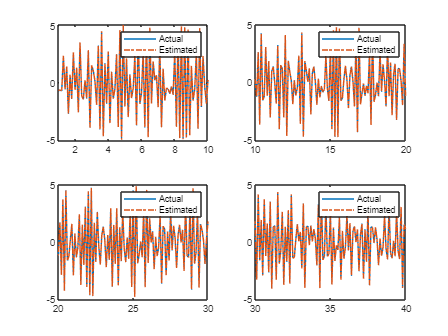

% Solving for Linear Least Squares
theta_hat = inv(U'*U)*U'*y;
y_hat = U*theta_hat;


figure()

subplot(2,2,1)
plot(t,y,t,y_hat,'-.')
legend('Actual','Estimated')
xlim([1,10])

subplot(2,2,2)
plot(t,y,t,y_hat,'-.')
legend('Actual','Estimated')
xlim([10,20])

subplot(2,2,3)
plot(t,y,t,y_hat,'-.')
legend('Actual','Estimated')
xlim([20,30])

subplot(2,2,4)
plot(t,y,t,y_hat,'-.')
legend('Actual','Estimated')
xlim([30,40])

%% Evaluation Metrics
disp("----------------Model Evaaluation Report-------------------")

----------------Model Evaaluation Report-------------------



SST = sum((y-mean(y)).^2);
SSE = sum((y-y_hat).^2);

R2 = 1 - (SSE/SST);

MSE = SSE/N;

fprintf('------> SSE : %.7f \n', SSE);

------> SSE : 0.1486299 


fprintf('------> MSE : %.7f \n', MSE);

------> MSE : 0.0001453 


fprintf('------> R2  : %.7f \n', R2);

------> R2  : 0.9999739 



disp("===========================================================")

### D:

Yes. Since equations are at least equalt to the number of unkonwn parameters, it is possible to find a unique solution.